# **SISTEMAS DE CONTROL DISCRETO                                **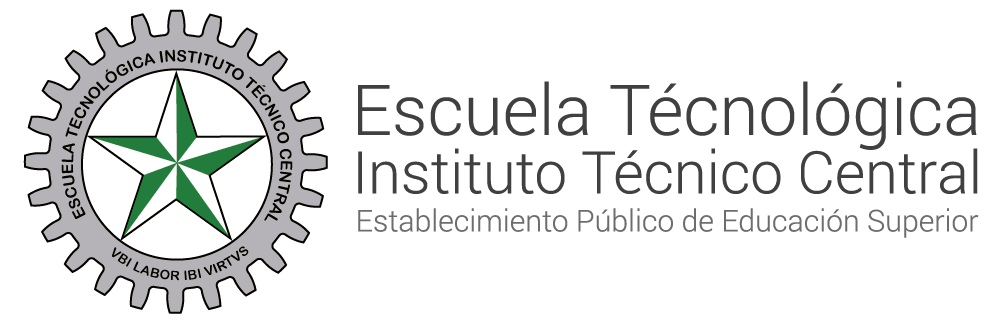

# **Lugar Geometrico de las Raícez **

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO MS.c

#### Coautor: HEISSY BRIGITTE CASTRO HURTADO

#### OBJETIVO

Al finalizar esta sesión, los estudiantes serán capaces de entender y aplicar el concepto de lugar geométrico de las raíces en el análisis de sistemas de control. Identificarán cómo varían las raíces de un polinomio característico al modificar los parámetros del sistema y cómo esto impacta la estabilidad y la dinámica del sistema. Además, desarrollarán habilidades para utilizar herramientas analíticas y computacionales para trazar y analizar estos lugares geométricos, facilitando así el diseño y ajuste de controladores.

**LGR**

El Lugar Geométrico de las Raíces (LGR) es una técnica esencial en el análisis y diseño de sistemas de control. Esta **herramienta gráfica **proporciona una visión clara de cómo las raíces de la ecuación característica de un sistema, es decir, los polos del sistema se desplazan en el plano complejo en respuesta a variaciones en los parámetros del sistema. Entender cómo se comportan estas raíces es fundamental porque determinan directamente la estabilidad y el comportamiento dinámico del sistema.

## VALOR MARGINAL DE K PARA ESTABILIDAD

Siendo $k$ el parametro variable o ganancia, es quien cambia o modifica la respuesta sistema de control al cual se aplica. Teniendo limites 

Cuando se tiene la ecuacion caracteristica del sistema de control en tiempo discreto, es necesario realizar el analisis desde el paso 1 para encontrar los LGR, en este caso el paso 1 se debe realizar de forma inverza, con el fin de llevar la ecuacion caracteristica a la funcion de transferencia inicial. 

#### Paso 1 de forma inverza

Obtener la funcion de transferencia apartir de la ecuación característica 


$$1+ F(z)=0$$


en donde $F\left(z\right)$ esta representado por la función de transferencia $\frac{k*N\left(z\right)}{D\left(z\right)}$ 


$$1+\frac{k*N\left(z\right)}{D\left(z\right)}=0$$


se remplaza 1 para hacer un denominador comun para ambos terminos.


$$\frac{D\left(z\right)}{D\left(z\right)}+\frac{\textrm{kN}\left(z\right)}{D\left(z\right)}=0$$
 
$$\longrightarrow$$
 
$$\frac{D\left(z\right)+\textrm{kN}\left(z\right)}{D\left(z\right)}=0$$


pasa el denominador a multiplicar despues del igual.


$$D\left(z\right)+\textrm{kN}\left(z\right)=0*D\left(z\right)$$


quedando la siguiente expresion 


$$D\left(z\right)+\textrm{kN}\left(z\right)=0$$


como se evidencia esta expresion se asemeja a la ecuacion caracteristica, determinado asi la funcion de transferencia donde los elementos que hacen parte del numerador son los que incluyen k, mientras los que no incluyen k son parte del denominador.


$$\textrm{FT}=\frac{\textrm{kN}\left(z\right)}{D\left(z\right)}$$


#### Ejemplo

Dada la siguiente ecuacion caracteristica del sistema de control en tiempo discreto, contruya el LGR pra K>0. Determine el valor marginal de K para estabilidad. 

## 
$${\mathit{\mathbf{z}}}^2 +\left(0,1k-1\right)z+0,5=0$$


Primeros se relizan los procedimientos algebraicos correspondientes:


$${\mathit{\mathbf{z}}}^2 +0,1\textrm{kz}-z+0,5=0$$


Pasar la ecuancion carcateristica a la forma $\textrm{FT}=\frac{\textrm{kN}\left(z\right)}{D\left(z\right)}$; teniendo en cuenta que los terminos del nuemerador son los que incluyen k


$${\mathit{\mathbf{z}}}^2 +0,1\textrm{kz}-z+0,5=0\;\;\;\;\longrightarrow \;\;\;\textrm{FT}=\frac{0,1\textrm{kz}}{{\mathit{\mathbf{z}}}^2 -z+0,5}\;\;\;\;$$


Se factoriza la k en el nuerando obteniendo finalmente la siguiente funcion de transferencia. 


$$\textrm{FT}=\frac{k\left(0,1\mathit{\mathbf{z}}\right)}{{\mathit{\mathbf{z}}}^2 -z+0,5}\;\;\;\;$$


Comprobando por medio de codigo obtenmos 

clear all
clc
numerador = [0.1, 0];   % Numerador del sistema
denominador = [1, -1, 0.5];   % Denominador del sistema
fprintf('* Función de Transferencia *\n');

* Función de Transferencia *



% Definir el tiempo de muestreo
ts = 1; % Tiempo de muestreo

% Crear el sistema de transferencia discreto
fprintf('* Función de Transferencia Discreta *\n');

* Función de Transferencia Discreta *


sistema = tf(numerador, denominador, ts)

sistema =
 
      0.1 z
  -------------
  z^2 - z + 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.



Teniendo la *FT, *se procede al paso 2.

#### Paso 2

Encontrar y dibujar los puntos de inicio y final. Ceros y Polos

De la siguiente forma se hallan los Ceros del sistema


$$\frac{0,1\mathit{\mathbf{z}}}{{\mathit{\mathbf{z}}}^2 -z+0,5}\;\;\;\;$$


De la funcion se toman los terminos del numerador.


$$0,1\mathit{\mathbf{z}}=0$$



$$z=0*0,1$$



$$z=0$$


Cantidad de ceros = 1

fprintf('*** Calcular ceros del sistema ***\n');

*** Calcular ceros del sistema ***


ceros = zero(sistema)

ceros = 0

De la siguiente forma se hallan los Polos del sistema


$$\frac{0,1\mathit{\mathbf{z}}}{{\mathit{\mathbf{z}}}^2 -z+0,5}$$


De la funcion se toman los terminos del denominador.


$${\mathit{\mathbf{z}}}^2 -z+0,5=0$$


Aplicando la ecuación cuadrática de la forma $z=\frac{-b\pm \sqrt{b^2 -4\textrm{ab}}}{2a}$ se obtiene:


$$z=\frac{-\left(-1\right)\pm \sqrt{{\left(-1\right)}^2 -4\left(1\right)\left(0,5\right)}}{2\left(1\right)}$$



$$z=\frac{1\pm \sqrt{1-2\;}}{2}\;\;\;\longrightarrow \;\;\;z=\frac{1\pm \sqrt{-1}}{2}\;\;\;\;$$



$$z=\frac{1+1i}{2}$$
      
$$z=\frac{1-1i}{2}$$


$z_1 =0,5+0,5i$ y $z_2 =0,5-0,5i$ 


$$\textrm{z1}=0,5+0,5i$$



$$\textrm{z2}=0,5-0,5i$$


Cantidad de polos = 2

% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('*** Calcular polos del sistema usando matlab ***\n');

*** Calcular polos del sistema usando matlab ***


polos = pole(sistema)

polos =    0.5000 + 0.5000i
   0.5000 - 0.5000i


fprintf('*** Graficar el Lugar Geométrico de las Raíces (LGR) ***\n');

*** Graficar el Lugar Geométrico de las Raíces (LGR) ***


figure;
rlocus(sistema);
title('Lugar Geométrico de las Raíces (LGR) del Sistema Discreto');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

hold on;
plot(real(polos), imag(polos), 'rx', 'MarkerSize', 20, 'LineWidth', 2); % Polos (x en rojo)
plot(real(ceros), imag(ceros), 'go', 'MarkerSize', 20, 'LineWidth', 2); % Ceros (o en verde)

for k = 1:length(polos)
    text(real(polos(k)), imag(polos(k)), sprintf('Polo %d', k), 'VerticalAlignment', 'bottom');
end
for k = 1:length(ceros)

    text(real(ceros(k)), imag(ceros(k)), sprintf('Cero %d', k), 'VerticalAlignment', 'top');
end


fprintf('polos del sistema\n');

polos del sistema


n_polos = length(polos)

n_polos = 2

fprintf('Ceros del sistema\n');

Ceros del sistema


n_ceros = length(ceros)

n_ceros = 1

#### Paso 3

A continuación se procede a encontrar las asintotas y sus angulos:

para en contrar las asintotas se usa la siguiente formula. 


$$\frac{180\left(2N+1\right)}{n-m}=0$$



$$\begin{array}{l}
N=k\;;\;k=0\\
n=\textrm{numero}\;\textrm{de}\;\textrm{polos}\\
m=\textrm{numero}\;\textrm{de}\;\textrm{ceros}
\end{array}$$


remplazamos los valores del sistema


$$\frac{180\left(2\left(0\right)+1\right)}{2-1}=0$$



$$\frac{180}{1}=180$$


%%
n_asintotas = n_polos - n_ceros

n_asintotas = 1

angulo_asintotas = 0

centro_asintotas = 1.0000

*** Ángulos de las asíntotas ***


angulo_asintotas = 0

if n_asintotas > 0
    suma_polos = sum(real(polos));
    suma_ceros = sum(real(ceros));
    angulo_asintotas = (0:n_asintotas-1) * (180 / n_asintotas)   
    centro_asintotas = (suma_polos - suma_ceros) / n_asintotas
    fprintf('*** Ángulos de las asíntotas ***\n');
    angulo_asintotas = (0:n_asintotas-1) * (180 / n_asintotas)

    % Graficar cada asíntota
    for k = 1:n_asintotas
        theta = angulo_asintotas(k) * pi / 180; % Convertir a radianes
        x_asintota = real(centro_asintotas) + [-100, 100] * cos(theta);
        y_asintota = imag(centro_asintotas) + [-100, 100] * sin(theta);
        plot(x_asintota, y_asintota, '--k', 'LineWidth', 1); % Asíntota en línea negra discontinua
    end
end

#### Paso 4

Se procede hallando la intersección de las asintotas, usando la siguiente formula:


$$\sigma =\frac{\Sigma \textrm{polos}-\Sigma \textrm{ceros}}{n-m}$$


Reemplazando los valores dle sistema se obtiene


$$\sigma =\frac{\left(0,5+0,5i+\left(0,5-0,5i\right)\right)-\left(0\right)}{2-1}$$



$$\sigma =\frac{\left(0,5+0,5i+0,5-0,5i\right)-\left(0\right)}{1}$$



$$\sigma =\frac{\left(1+0i\right)-\left(0\right)}{1}$$



$$\sigma =\frac{1+0i}{1}\;\;\;\;\;\longrightarrow \sigma =1$$


%%
n_asintotas = n_polos - n_ceros

n_asintotas = 1

if n_asintotas > 0
suma_polos = sum(real(polos));
suma_ceros = sum(real(ceros));
fprintf('Punto de intersección de las asíntotas\n');
centro_asintotas = (suma_polos - suma_ceros) / n_asintotas
end

Punto de intersección de las asíntotas


centro_asintotas = 1.0000

#### Paso 5

El siguiente paso es encontrar la interseccion de las asintotas, utilizando la ecuacion:


$$1+kG\left(z\right)=0\;\;;\;\;\;\;\;\;G\left(z\right)=\frac{0,1\mathit{\mathbf{z}}}{{\mathit{\mathbf{z}}}^2 -z+0,5}\;\;\;\;$$
     


$$kG\left(z\right)=-1\;\;\;\longrightarrow \;\;\;\;k=-\frac{1}{G\left(z\right)}$$



$$k=-\frac{1}{G\left(z\right)}\;\;\;\longrightarrow \;\;\;\;k=-\frac{1}{\;\frac{0,1\mathit{\mathbf{z}}}{{\mathit{\mathbf{z}}}^2 -z+0,5}\;\;\;\;}$$



$$k=-\frac{{\mathit{\mathbf{z}}}^2 -z+0,5}{0,1\mathit{\mathbf{z}}}$$


Para necontrar los puntos de ruptura es necesario derivar la ecuacion anterior asi:


$$\frac{\textrm{dk}}{\textrm{dz}}=\frac{d\;}{\textrm{dz}}\left(\frac{-\left({\mathit{\mathbf{z}}}^2 -z+0,5\right)}{0,1\mathit{\mathbf{z}}}\right)$$



$$\;\;\;\;\;-\frac{d\;}{\textrm{dz}}\left(\frac{{\mathit{\mathbf{z}}}^2 -z+0,5}{0,1\mathit{\mathbf{z}}}\right)$$


Para derivar dividimos en 3 fracciones el termino.


$${\left(\frac{\mathit{\mathbf{f}}}{g}\right)}^{\prime } =\frac{{\mathit{\mathbf{f}}}^{\prime } *g-g^{\prime } *f}{g^2 }$$



$${\left(\frac{{\mathit{\mathbf{z}}}^2 -z+0,5}{0,1\mathit{\mathbf{z}}}\right)}^{\prime } =-\frac{1}{0,1}\left(\frac{\left({\left({\mathit{\mathbf{z}}}^2 -z+0,5\right)}^{\prime } *\left(\mathit{\mathbf{z}}\right)\right)-\left({\left(\mathit{\mathbf{z}}\right)}^{\prime } *{\left({\mathit{\mathbf{z}}}^2 -z+0,5\right)} \right)}{{\left(\mathit{\mathbf{z}}\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{1}{0,1}\left(\frac{\left(\left.2z^2 -1\right)*\left(z\right)\right)-\left(\left(1\right)*{\mathit{\mathbf{z}}}^2 -z+0,5\right)}{{\left(0,1\mathit{\mathbf{z}}\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{1}{0,1}\left(\frac{\left(2z^2 -z\right)-\left(z^2 -z+0,5\right)}{{\left(\mathit{\mathbf{z}}\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{1}{0,1}\left(\frac{2z^2 -z-z^2 +z-0,5}{{\left(\mathit{\mathbf{z}}\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\frac{1}{0,1}\left(\frac{z^2 -0,5}{{\left(\mathit{\mathbf{z}}\right)}^2 }\right)$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=-\left(\frac{z^2 -0,5}{{\left(0,1\mathit{\mathbf{z}}\right)}^2 }\right)$$


 
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{{-z}^2 +0,5}{{\left(0,1\mathit{\mathbf{z}}\right)}^2 }$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{{-z}^2 +0,5}{{\left(0,1\mathit{\mathbf{z}}\right)}^2 }$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{{-z}^2 +0,5}{{\left(0,1\mathit{\mathbf{z}}\right)}^2 }=0$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;{-z}^2 +0,5=0*{\left(0,1\mathit{\mathbf{z}}\right)}^2 \;\;\;\;\;\;\;\;\;\;\longrightarrow \;\;\;\;\;\;\;\;\;\;\;\;\;{-z}^2 +\frac{1}{2}=0\;\;\;$$


Aplicando la ecuación cuadrática de la forma $z=\frac{-b\pm \sqrt{b^2 -4\textrm{ab}}}{2a}$ se obtiene:


$$z=\frac{-\left(0\right)\pm \sqrt{{\left(0\right)}^2 -4\left(-1\right)\left(0,5\right)}}{2\left(-1\right)}$$



$$z=\frac{-\left(0\right)\pm \sqrt{0-\left(-2\right)}}{-2}$$



$$z=\frac{0\pm \sqrt{2}}{-2}$$



$$z=0+\frac{\sqrt{2}}{-2}$$
                     
$$z=0-\frac{\sqrt{2}}{-2}$$


Para resolver este polinomio y encontrar los puntos de ruptura se usa el siguiente codigo 

Polinomio=[-1, 0, -0.5];
disp('puntos de ruptura:');

puntos de ruptura:


disp(roots(Polinomio));

   0.0000 + 0.7071i
   0.0000 - 0.7071i



#### **Paso 6**

#### **Criterio de JURY - Condiciones de estabilidad**

Finalmente para este paso se usa la funcion de transferencia, tomando el denominador de esta primero se identifican las condiciones de estabilidad y despues se aplica el criterio de JURY; si el sistema no cumple con las condiciones significa que no el mismo es inestable, las condiciones a evaluar son las siguientes:


$$\frac{k\left(0,1\mathit{\mathbf{z}}\right)}{{\mathit{\mathbf{z}}}^2 -z+0,5}$$



$$P\left(z\right)={\mathit{\mathbf{z}}}^2 -z+0,5$$


Condiciones: 

## $\left|a_0 \right|<a_n$ esta condicion indica que, deacuerdo con el polinomio a evaluar el ultimo termino debe ser menor al primero, en este caso el pirmer termino ${\mathit{\mathbf{z}}}^3$ que acompaña la z es 1 y el ultimo es $0,5$, dando como respuesta que primera condicion se cumple.

                    
$${\mathit{\mathbf{z}}}^2 -z+0,5=$$

$$\overbrace{{\mathit{\mathbf{z}}}^2 } -z+\overbrace{0,5} \;\;\;\;\;\;\;\;\longrightarrow \;\;\;\;\;\left|a_0 \right|<a_n =0,51<1$$
         

## $P\left(z\right)|z_{=1} >0,$ para esta condicion se requiere remplazar en el polinomio las z por el valor de 1, y el resultado de las opraciones algebraicas debe ser mayor que cero. Para esta condicion el polinomio cumple puesto que el valor resultante es mayor que 0 

                    
$$\begin{array}{l}
{\mathit{\mathbf{z}}}^2 -z+0,5={\left(1\right)}^2 -1+0,5\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\longrightarrow \;\;\;\;\;\;\;\;=1-1+0,5\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=0,5\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


## $\begin{array}{l}
P\left(z\right)|z_{=-1} >0\;\textrm{para}\;n\;\textrm{par}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;<0\;\textrm{para}\;n\;\textrm{impar}
\end{array}$,   esta condicion indica que se requiere remplazar en el polinomio las z por el valor -1, y el resultado de las operaciones algebraicas tiene dos posibilidades de acuerdo al grado (*n) *del polinomio. Si el polinomio es de grado par el valor debe ser mayor que 0; si el polinomio el de grado impar el valor resultante debe ser menor que 0. En el caso de este polinomio que es de grado par, el resultado debera ser mayor que 0, esta condicion si la cumple. 

                      
$$\begin{array}{l}
{\mathit{\mathbf{z}}}^2 -z+0,5={\left(-1\right)}^2 -\left(-1\right)+0,5\;\;\;\;\;\;\;\;\;\;\;\;\;\longrightarrow \;\;\;\;\;\;\;\;=1+1+0,5\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=2,5\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


Teniendo en cuenta que las condiciones de estabilidad cumplen, se procede a aplicar el criterio de **JURY**

#### Criterio de JURY

El criterio de JURY es un metodo para encontrar los valores marginales de k, asi mismo identificar el rango de ganancia que puede tener el sistema sin perder la estabilidad. 

Para realizar el criterio de JURY, se toma la ecuacion caracteristica entregad desde el inicio, y se organizan en una fila los terminos que acompañan la z (en orden de z)  menor a mayor; en una fila inferior a esta se organiza de nuevo los terminos que acompañan la z (en orden de z) pero de mayor a menor, de la siguiente forma:


$${\mathit{\mathbf{z}}}^2 +\left(0,1k-1\right)z+0,5=0$$



$$0,5\;\;\;\;\;\;\left(0,1k-1\right)\;\;\;\;\;\;\;\;\;\;1$$



$$\;1\;\;\;\;\;\;\;\;\;\;\left(0,1k-1\right)\;\;\;\;\;\;\;\;0,5$$


Despues de organizar los terminos, el siguiente paso es hacer la tabla de JURY; la tabla se forma encontrando los valores de las determinantes entre los dos terminos ubicados en la primera columna, inicialmente por los dos terminos de la ultima columna y luego por los terminos de la siguiente columna. En este caso se obtendra para comenzar 2 terminios b1 y b2.


$$\textrm{b1}=\left\lbrace \begin{array}{ll}
0,5 & 1\\
1 & 0,5
\end{array}\right.\;\;\;=\;\;\;\left(0,5*0,5\right)-\left(1*1\right)\;\;=0,25-1\;\;=\;\;-0,75$$
 


$$\textrm{b2}=\left\lbrace \begin{array}{ll}
0,5 & \left(0,1k-1\right)\\
1 & \left(0,1k-1\right)
\end{array}\;\;\;=\;\;\;\left(0,5*\left(0,1k-1\right)\right)-\left(1*\left(0,1k-1\right)\right)\;\;=\left(0,05k-0,5\right)-\left(0,1k-1\right)=0,05k-0,5-0,1k+1=-0,05k+0,5\right.$$


Los resultados obtenidos b1 y b2, se organizan en un nuevo polinomio de la siguiente forma:


$$-0,75-0,05+0,5=0$$


En este caso se organizan en la tabla, la primera fila en el orden en el cual se encontraron los resultados; en la fila inferior a esta los resultados en sentido contrario del ultimo al primero; por ultimo se encuentran los determinantes hallando c1, de la siguiente forma:


$$-0,75\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-0,05k+0,5$$



$$-0,05k+0,5\;\;\;\;\;\;-0,75$$
     


$$\textrm{c1}=\left\lbrace \begin{array}{ll}
-0,75 & -0,05k+0,5\\
-0,05k+0,5 & -0,75
\end{array}\;\;\;=\;\;\;\left(-0,75*-0,75\right)-\left(\left(-0,05k+0,5\right)*\left(-0,05k+0,5\right)\right)=\left(0,5625\right)-\left(0,0025k^2 -0,025k-0,025k+0,25\right)\right.$$
    
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\;\;\;\left(0,5625\right)-\left(0,0025k^2 -0,05k+0,25\right)\;=\;\;0,5625-0,0025k^2 +0,05k-0,25\;\;=\;-0,0025{\mathit{\mathbf{k}}}^2 +0,05\mathit{\mathbf{k}}-0,3125$$


para comprobar los resultados anteriores se usa el codigo acontinuacion.

%matriz jury p1
syms k % Declarar la variable simbólica

A = [0.5, 0.1*k - 1, 1; 
     1, 0.1*k - 1, 0.5]; % Matriz de 2 filas y 3 columnas

disp('Terminos inicales:');

Terminos inicales:


disp(A); % Mostrar la matriz

$$\left(\begin{array}{ccc} \frac{1}{2} & \frac{k}{10}-1 & 1\\ 1 & \frac{k}{10}-1 & \frac{1}{2} \end{array}\right)$$


%matriz b1
fprintf('Matriz b1 \n');

Matriz b1 


b1=[0.5, 1; 1, 0.5]

b1 =     0.5000    1.0000
    1.0000    0.5000


fprintf('Determiante b1 \n');

Determiante b1 


b1=det(b1)% Calcular el determinante

b1 = -0.7500


%matriz b2
b2 = [0.5, (0.1*k - 1);1, (0.1*k - 1)]; % Definir la matriz
disp('Matriz b2:');

Matriz b2:


disp(b2); % Mostrar la matriz

$$\left(\begin{array}{cc} \frac{1}{2} & \frac{k}{10}-1\\ 1 & \frac{k}{10}-1 \end{array}\right)$$

det_b2 = det(b2); % Calcular el determinante
disp('Determinante de b2:');

Determinante de b2:


disp(det_b2); % Mostrar el determinante

$$\frac{1}{2}-\frac{k}{20}$$

expr1 = 1/2 - k/20;  % Define la expresión
expr_decimal = vpa(expr1);       % Convierte a decimal
disp(expr_decimal);

$$0.5-0.05\,k$$


c1 = [b1, det_b2; det_b2, b1]; % Definir la matriz
disp('Matriz c1:');

Matriz c1:


disp(c1); % Mostrar la matriz

$$\left(\begin{array}{cc} -\frac{3}{4} & \frac{1}{2}-\frac{k}{20}\\ \frac{1}{2}-\frac{k}{20} & -\frac{3}{4} \end{array}\right)$$

det_c1 = det(c1); % Calcular el determinante
disp('Determinante de c1:');

Determinante de c1:


disp(det_c1); % Mostrar el determinante

$$-\frac{k^{2}}{400}+\frac{k}{20}+\frac{5}{16}$$

expr = -k^2/400 + k/20 + 5/16;  % Define la expresión
expr_decimal = vpa(expr);       % Convierte a decimal
disp(expr_decimal);

$$-0.0025\,k^{2}+0.05\,k+0.3125$$


syms k real
% Definir las filas de la tabla
z0 = [1/2, 1, 1/2, 1, -3/4, 1/2 - k/20,];
z1 = [0, 0, k/10 - 1, k/10 - 1, 1/2 - k/20, -3/4];
z2 = [1, 1/2, 0, 0, 0, 0];
Resultados = [0, -3/4, 0, 1/2 - k/20, 0, -k^2/400 + k/20 + 5/16];

% Convertir todos los valores a decimales
z0_decimal = vpa(z0);
z1_decimal = vpa(z1);
z2_decimal = vpa(z2);
Resultados_decimal = vpa(Resultados);

% Mostrar la tabla con valores decimales
tabla = table(z0_decimal', z1_decimal', z2_decimal', Resultados_decimal', ...
    'VariableNames', {'z0', 'z1', 'z2', 'Resultados'});
disp(tabla);

         z0              z1         z2               Resultados          
    ____________    ____________    ___    ______________________________

    0.5             0               1.0    0                             
    1.0             0               0.5    -0.75                         
    0.5             0.1*k - 1.0     0      0                             
    1.0             0.1*k - 1.0     0      0.5 - 0.05*k                  
    -0.75           0.5 - 0.05*k    0      0                             
    0.5 - 0.05*k    -0.75           0      - 0.0025*k^2 + 0.05*k + 0.3125



c1 es el valor resultante de la determinante, en el caso de esta ecuacion se hallo un polinomio cuadratico. por tal motimo como este es el valor encontrado, se despeja k de la siguinte forma:


$$-0,0025k^2 +0,05k-0,3125>0$$


      
$$-0,0025\left(k^2 +20k-125\right)>0$$


                    
$$\left(k^2 +20k-125\right)>0*-0,0025$$


                   
$$\left(k^2 +20k-125\right)>0$$



$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(k-25\right)\left(k+5\right)>0$$


De esta forma se obtienen 2 posibles resultados para *k, por una parte *$\mathit{\mathbf{k}}=25$ y por la otra $\mathit{\mathbf{k}}=-5$; obteniendo el siguiente rango:


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-5<k<25$$


### Sabiendo que k debe ser mayor que cero los valers marginales para $\mathit{\mathbf{k}}$ entan en el rango de :

 
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0<\mathit{\mathbf{k}}<25$$


Comporbando los resultados con codigo matlab se encuentra:

pc=[-0.0025, 0.05, 0.3125];
valoresk =roots(pc)

valoresk =     25
    -5


#### Respuesta del sistema en tiempo discreto

Para culminar con el ejemplo, los valores marginales para k ya comprobados por matlab, serian 25 y -5, pero como se requiere desde el inicio k debe ser mayor a 0, por tal motivo el rango sera de 0 a 25. A continucacion se grafica los LGR con el valor de k determinado.

% estabilidad del sistema
numerador = [0.1, 0];   % Numerador del sistema
denominador = [1, -1, 0.5];   % Denominador del sistema

% Definir el tiempo de muestreo
ts = 1; % Tiempo de muestreo

% Crear el sistema de transferencia discreto

sistema = tf(numerador, denominador, ts)

sistema =
 
      0.1 z
  -------------
  z^2 - z + 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.




% Definir el rango de ganancias k para el análisis
k = (0:0.1:25);  % Rango de valores de ganancia

% Graficar el Lugar Geométrico de las Raíces (LGR)
fprintf('* Representacion de estabilidad *\n');

* Representacion de estabilidad *


figure;
rlocus(sistema,k);
title('Lugar Geométrico de las Raíces (LGR) con k definido');
xlabel('Parte Real');
ylabel('Parte Imaginaria');
grid on;

La respuesta del sistema al escalon unitario aplicando una ganacia de 0 a 25 es la siguiente 

k=7

k = 7

numerador = [k*0.1 0];
denominador = [1, -1, 0.5];
Ts = 1; 
sys = tf(numerador, denominador,Ts)/(1+tf(numerador, denominador,Ts))

sys =
 
        0.7 z^3 - 0.7 z^2 + 0.35 z
  ---------------------------------------
  z^4 - 1.3 z^3 + 1.3 z^2 - 0.65 z + 0.25
 
Sample time: 1 seconds
Discrete-time transfer function.



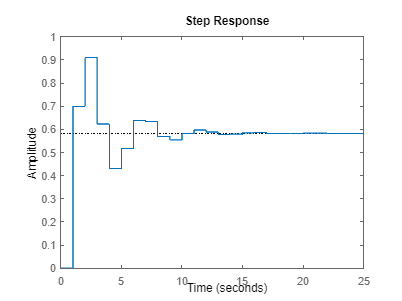


step(sys);